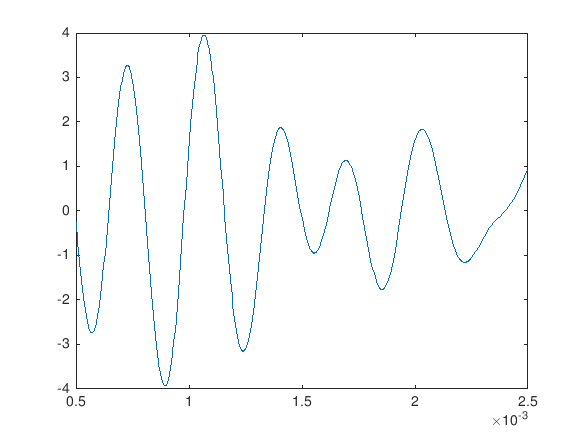

%This block is for generating the signal
n = 5;
f1 = 2e3;
f2 = 4e3;
syms x t;
x(t) = 0;
rng('shuffle')
frequencies = ((f2-f1)*rand([n,1])) + f1;
for i = 1:1:n
    x(t) = x(t) + sin(2*pi*frequencies(i)*t);
end
%Run the following if needed to plot the signal
fplot(t,x(t),[1/f1 5/f1]);

%This block is for sampling
i = 0;
sampled_signal = [];
fs = 8e3%Set sampling frequency

fs = 8000

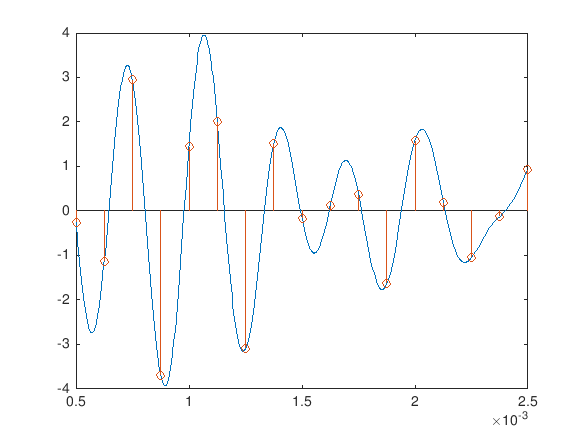

while (i/fs<0.05)
    sampled_signal = [sampled_signal x(i/fs)];
    i = i+1;
end
%Run the following if needed to plot the signal
t1 = 0:1/fs:0.01;
range = t1>=1/f1 & t1<=5/f1; %(range of the axis)
t2 = t1(range);
x1 = sampled_signal(range);
hold on
stem(t2,x1);
hold off

%This block is for reconstruction
syms xs %xs is reconstructed signal
xs(t) = 0;
for a = 1:1:i-1
    xs(t) = xs(t) + (sampled_signal(a+1)*sinc((fs*t)-a));
end
%Following for plotting
hold on 
fplot(t,xs(t),[1/f1 5/f1]);
hold off